## The basic components of a synthesizer are made in a), b), c), d), and then in e) i simply mix it together

% Assignment 2 - 246185
clear all
clc


% Remember to do the following

% Include time-domain plots
% Include frequency-domain plots
% Justify parameter choices
% Explain DSP principles used

% NOTE:
% Most of the parts has been solved in function files that i
% then use in this file to make stuff with, there should be 3
% function files delivered with this

## a) A function generating sinusoids/trains of square waves/triangles/saw tooths

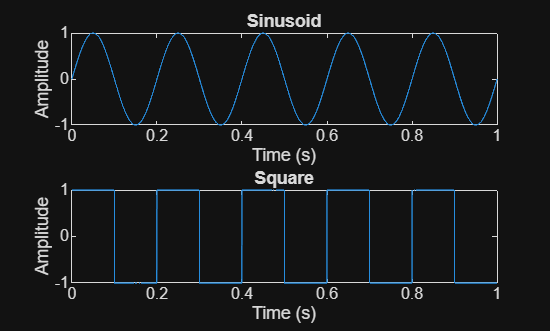

% Test to see if it works
a = 1;
f = 5;
phi = 0;
fs = 44100;
T_s = 1;

[t_sin, sin_sig] = generate_wave(a, f, phi, fs, T_s, 'sin');
[t_squ, squ_sig] = generate_wave(a, f, phi, fs, T_s, 'squ', 0.5);
[t_tri, tri_sig] = generate_wave(a, f, phi, fs, T_s, 'tri');
[t_saw, saw_sig] = generate_wave(a, f, phi, fs, T_s, 'saw');

figure;

subplot(2,1,1);
plot(t_sin, sin_sig);
xlabel('Time (s)')
ylabel('Amplitude')
title('Sinusoid');

subplot(2,1,2);
plot(t_squ, squ_sig);
xlabel('Time (s)')
ylabel('Amplitude')
title('Square');

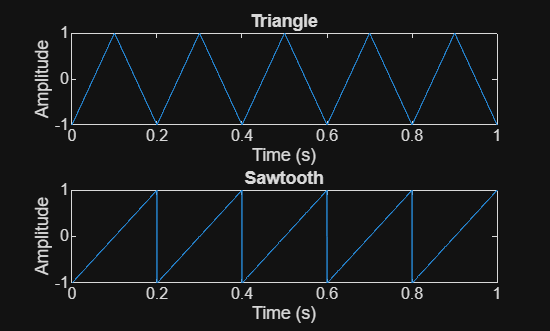


figure
subplot(2,1,1);
plot(t_tri, tri_sig);
xlabel('Time (s)')
ylabel('Amplitude')
title('Triangle');

subplot(2,1,2);
plot(t_saw, saw_sig);
xlabel('Time (s)')
ylabel('Amplitude')
title('Sawtooth');

## Frequency plots (Wavegen)

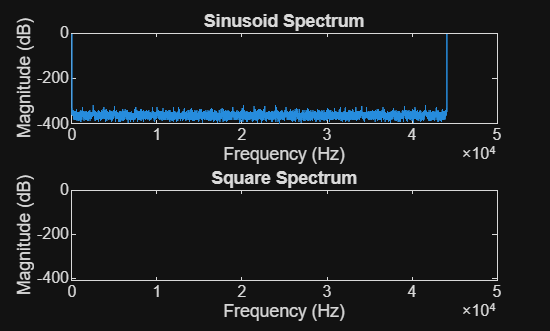

% Here i use the function 'make_spectrum' from week 3 as a start
% to enter the frequency domain
[SIN, SIN_freq] = make_spectrum(sin_sig, fs);
[SQU, SQU_freq] = make_spectrum(squ_sig, fs);
[TRI, TRI_freq] = make_spectrum(tri_sig, fs);
[SAW, SAW_freq] = make_spectrum(saw_sig, fs);

% getting the magnitude in dB
sin_mag_dB = 20*log10(abs(SIN));
squ_mag_dB = 20*log10(abs(SQU));
tri_mag_dB = 20*log10(abs(TRI));
saw_mag_dB = 20*log10(abs(SAW));

% Plotting
figure
subplot(2,1,1)
plot(SIN_freq, sin_mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Sinusoid Spectrum')

subplot(2,1,2)
plot(SQU_freq, squ_mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Square Spectrum')

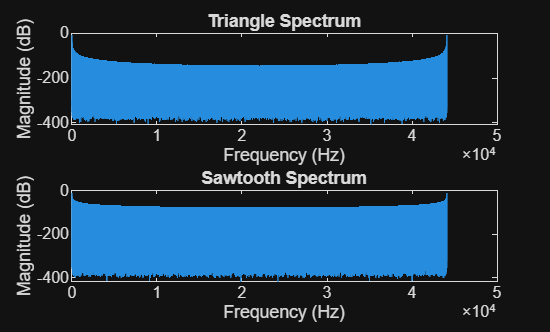


figure
subplot(2,1,1)
plot(TRI_freq, tri_mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Triangle Spectrum')

subplot(2,1,2)
plot(SAW_freq, saw_mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Sawtooth Spectrum')

## b) An ADSR-envelope generator with "Attack/Decay/Sustain/Release"

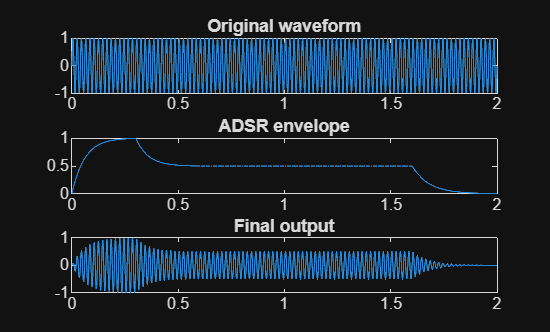

% Make exponential part next
% Parameters
fs = 44100;
T_s = 2;

% Waveform parameters
a = 1;
f = 50;
phi = 0;
type = 'sin';

% ADSR parameters
attack = 0.3;
decay = 0.3;
sustain = 0.5;
release = 0.4;

% Generate signal and envelope
[t, signal] = generate_wave(a, f, phi, fs, T_s, type);
envelope = ADSR_envelope(fs, T_s, attack, decay, sustain, release, 'exp');

% Apply envelope and plot
output = signal .* envelope;

figure;

subplot(3,1,1);
plot(t, signal);
xlabel('Time (s)')
ylabel('Amplitude')
title('Original waveform');

subplot(3,1,2);
plot(t, envelope);
xlabel('Time (s)')
ylabel('Amplitude')
title('ADSR envelope');

subplot(3,1,3);
plot(t, output);
xlabel('Time (s)')
ylabel('Amplitude')
title('Final output');


% Play
sound(output, fs);


## Frequency plots (ADSR)

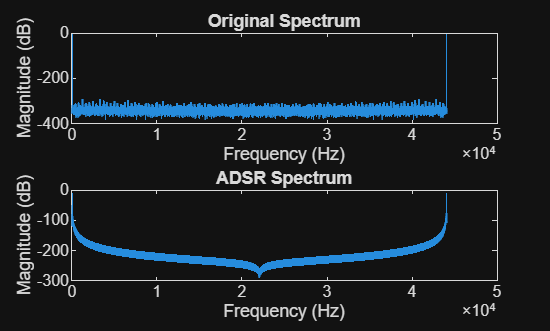

% Just like i did for wavegen
[WAVE, wave_freq] = make_spectrum(signal, fs);
[ADSR, ADSR_freq] = make_spectrum(output, fs);

wave_mag_dB = 20*log10(abs(WAVE));
ADSR_mag_dB = 20*log10(abs(ADSR));

% Plotting
figure
subplot(2,1,1)
plot(wave_freq, wave_mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Original Spectrum')

subplot(2,1,2)
plot(ADSR_freq, ADSR_mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('ADSR Spectrum')

## c) A filter element (low-/high-/band pass)

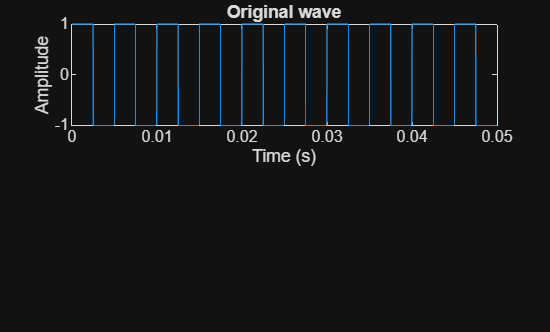

% Parameters
fs = 44100;
T_s = 0.05;

% Wave parameters
a = 1;
f = 200;
phi = 0;
type = 'squ';
duty = 0.5;

% Generate signal to apply the filters on
[t, signal] = generate_wave(a, f, phi, fs, T_s, type, duty);

% Applying the filters
LP = apply_filter(signal, fs, 'LP', 400, 4);
HP = apply_filter(signal, fs, 'HP', 1000, 4);
BP = apply_filter(signal, fs, 'BP', [1500 2500], 4);
BS = apply_filter(signal, fs, 'BS', [1500 2500], 4);

% Plotting to see the difference between them
figure;
subplot(2,1,1)
plot(t, signal);
xlabel('Time (s)')
ylabel('Amplitude')
title('Original wave');

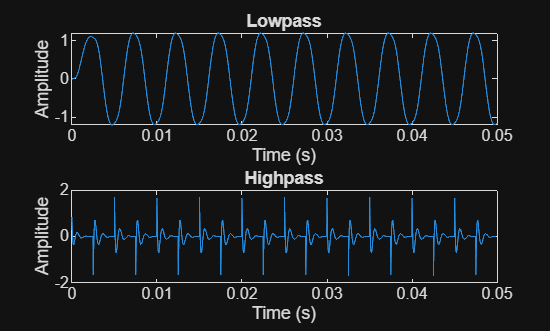


% Compared to the original wave the lowpass makes our square
% wave into basically a sinusoid which gives us a deeper sound
% which comes from the fact that we only let the low
% frequencies through, and attenuate everything else outside
% the scope of the lowpass filter, it ends up sounding like it
% has more "bass" sort of like how the sinusoid does
figure;
subplot(2,1,1);
plot(t, LP);
xlim([0 0.05])
xlabel('Time (s)')
ylabel('Amplitude')
title('Lowpass');

% As we can see from the highpass it functions sort of in the
% opposite way of the lowpass where we instead allow the higher
% frequencies through, and attenuate the lower ones
subplot(2,1,2);
plot(t, HP);
xlim([0 0.05])
xlabel('Time (s)')
ylabel('Amplitude')
title('Highpass');

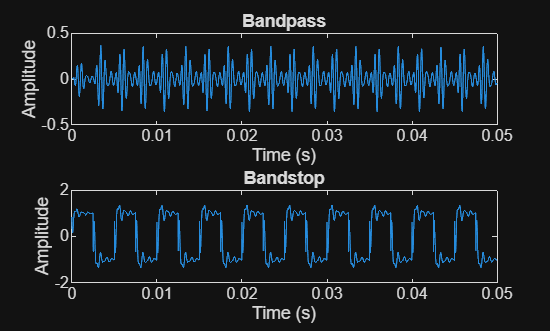


% The bandpass is instead of basing it on higher and lower
% frequencies, it has a frequency range it allows through
figure;
subplot(2,1,1);
plot(t, BP);
xlim([0 0.05])
xlabel('Time (s)')
ylabel('Amplitude')
title('Bandpass');

% The opposite of the bandpass, the bandstop instead has a
% range that it attenuates, and lets everything else through
subplot(2,1,2);
plot(t, BS);
xlim([0 0.05])
xlabel('Time (s)')
ylabel('Amplitude')
title('Bandstop');


% Below here are 5 different sounds, the original square wave,
% and the square wave going through the 4 different filters,
% it's a very short note, but you can still hear the
% difference. The reason for the short note is so we could see
% what was happening in the plots

## Original wave

sound(signal, fs);


## Lowpass

sound(LP, fs);


## Highpass

sound(HP, fs);


## Bandpass

sound(BP, fs);


## Bandstop

sound(BS, fs);


## Frequency plots (Filters)

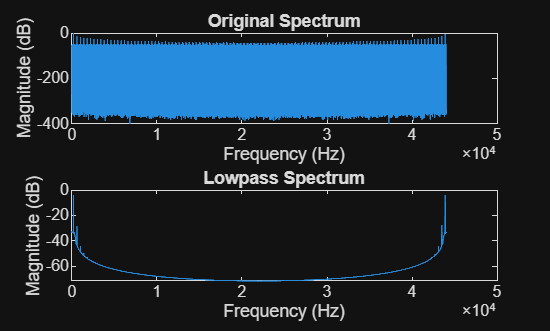

% Just like with wavegen
[OG, OG_freq] = make_spectrum(signal, fs);
[LoPa, LP_freq] = make_spectrum(LP, fs);
[HiPa, HP_freq] = make_spectrum(HP, fs);
[BaPa, BP_freq] = make_spectrum(BP, fs);
[BaSt, BS_freq] = make_spectrum(BS, fs);

OG_mag_dB = 20*log10(abs(OG));
LP_mag_dB = 20*log10(abs(LoPa));
HP_mag_dB = 20*log10(abs(HiPa));
BP_mag_dB = 20*log10(abs(BaPa));
BS_mag_dB = 20*log10(abs(BaSt));

% Plotting
figure
subplot(2,1,1)
plot(OG_freq, OG_mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Original Spectrum')

subplot(2,1,2)
plot(LP_freq, LP_mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Lowpass Spectrum')

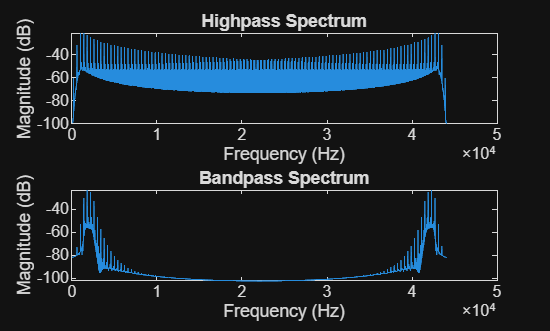


figure
subplot(2,1,1)
plot(HP_freq, HP_mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Highpass Spectrum')

subplot(2,1,2)
plot(BP_freq, BP_mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Bandpass Spectrum')

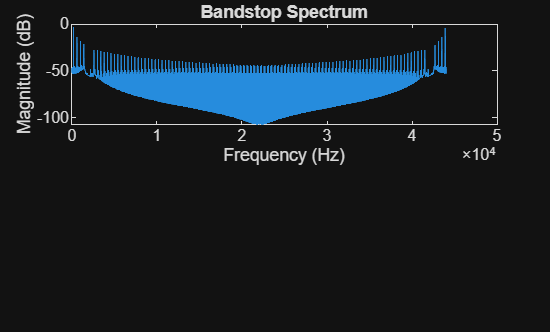


figure
subplot(2,1,1)
plot(BS_freq, BS_mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Bandstop Spectrum')

## d) An all-pass filter

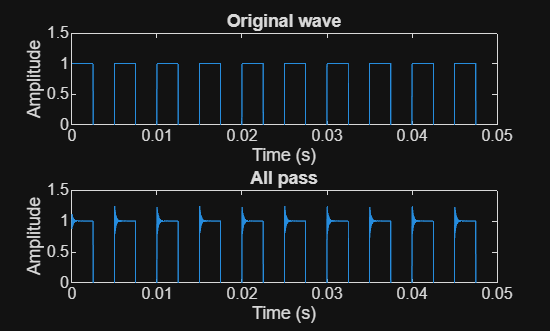

% We use the same function "apply_filter" where all-pass has
% been added as an option

% Parameters
fs = 44100;
T_s = 0.05;

% Wave parameters
a = 1;
f = 200;
phi = 0;
type = 'squ';
duty = 0.5;

% Generate waveform
[t, signal] = generate_wave(a, f, phi, fs, T_s, type, duty);

% Run it through all pass filter
AP = apply_filter(signal, fs, 'AP', 1000, 1);

% Plot
figure;
subplot(2,1,1)
plot(t, signal);
ylim([0 1.5])
xlabel('Time (s)')
ylabel('Amplitude')
title('Original wave');

subplot(2,1,2)
plot(t, AP);
ylim([0 1.5])
xlabel('Time (s)')
ylabel('Amplitude')
title('All pass');


% While you cant hear much difference with such a short sound,
% you can see from the plots that the all pass does have an
% effect on it, and it makes sense since the all pass does
% keep the amplitudes at the same, but changes the phase of
% the frequency components


## Frequency plots (All pass)

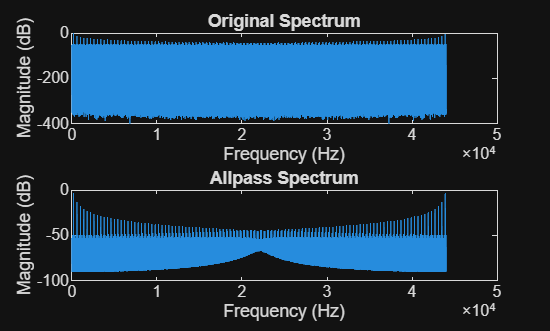

% Just like i did for wavegen
[WAVE, wave_freq] = make_spectrum(signal, fs);
[AlPa, AP_freq] = make_spectrum(AP, fs);

wave_mag_dB = 20*log10(abs(WAVE));
AP_mag_dB = 20*log10(abs(AlPa));

%Plotting
figure
subplot(2,1,1)
plot(wave_freq, wave_mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Original Spectrum')

subplot(2,1,2)
plot(AP_freq, AP_mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Allpass Spectrum')

## e) Mix (multiply/add) stuff up

Too many high frequencies? Apply a low-pass filter!

Not enough “ooomph”? Boost lower frequencies or modulate with a low-frequency sound.

Needs to be more “rough”? Try square wave instead of sinusoid.

More techno-like? Send a pulse train through a cascade of many (!) all-pass filters!

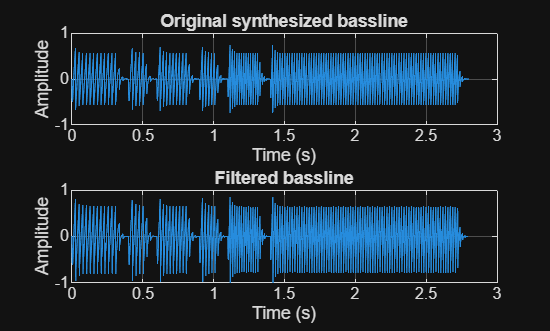

% Try doing the ones above and maybe other mixes

% First six bass notes
fs = 44100;
amplitude = 0.8;
BPM = 139;

% MIDI note numbers
midi_notes = [27 27 29 30 35 34];

% Convert MIDI to frequencies
frequencies = 440 .* 2.^((midi_notes-69)/12);

% Note durations in beats
note_beats = [1 0.5 0.75 0.5 0.75 3];

% Convert beats to seconds
%durations = note_beats * (60/139);

durations = [0.4 0.2 0.3 0.2 0.3 1.4];

%% ADSR settings
attack = 0.01;
decay = 0.10;
sustain = 0.7;
release = 0.08;

curve = 'exp';

%% Generate the six notes
bassline = [];

for k = 1:length(midi_notes)

    % Generate waveform
    [t, wave] = generate_wave( ...
        amplitude, frequencies(k), 0, fs, ...
        durations(k), 'saw');

    % Generate ADSR envelope
    envelope = ADSR_envelope( ...
        fs, durations(k), attack, decay, ...
        sustain, release, curve);

    % Apply envelope
    note = wave .* envelope;

    % Concatenate notes
    bassline = [bassline note];

end

%% Apply low-pass filter
filtered_bass = apply_filter( ...
    bassline, fs, 'LP', 500, 4);

%% Normalize
filtered_bass = filtered_bass / max(abs(filtered_bass));

%% Time vector
time = (0:length(filtered_bass)-1)/fs;

%% Plot
figure;

subplot(2,1,1);
plot(time, bassline);
title('Original synthesized bassline');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(time, filtered_bass);
title('Filtered bassline');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;


%% Playback
soundsc(filtered_bass, fs);

%% Make stereo
stereo_bass = [filtered_bass; filtered_bass].';

%% Save as 32-bit stereo WAV
audiowrite('fr feel good inc.wav', stereo_bass, fs, 'BitsPerSample', 32);

% Combine multiple synthesis elements

% (Designed a purposeful final sound effect)?

% Export final sound file


## AI disclaimer

% I have used AI mostly to help with making the code i had,
% into reusable functions in matlab so that it would sort of
% be easier to work with

% I also used AI to understand ADSR a bit better since i wasnt
% quite sure what exactly it was, i had an idea, but needed a
% bit more than that to work with

% I did also use AI to try to get the values to make the first
% 6 basslines in Gorillaz Feel Good Inc, although it didnt look
% great, but my friends found it funny so i kept it as my sound